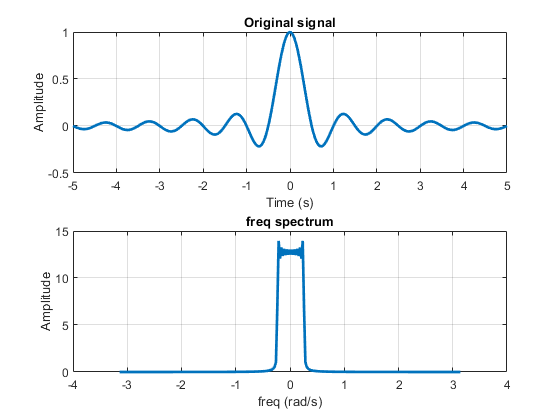

N = 256;
t = linspace(-5,5,256);
fs=1/(t(2)-t(1));

fs1=0.5*fs;
fs2=3*fs;
fs3=1.5*fs;

t1=-5:1/fs1:5;
t2=-5:1/fs2:5;
t3=-5:1/fs3:5;

x = sinc(2 * t);
x1 = sinc(2 * t1);
x2 = sinc(2 * t2);
x3 = sinc(2 * t3);
f_axis=linspace(-fs/2,fs/2,length(x));
f_axis1=linspace(-fs1/2,fs1/2,length(x1));
f_axis2=linspace(-fs2/2,fs2/2,length(x2));
f_axis3=linspace(-fs3/2,fs3/2,length(x3));

figure('Name', 'Original Signal');
subplot(211)
plot(t, x, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original signal');
grid on;
subplot(212)
plot(f_axis*2*pi/fs, abs(fftshift(fft(x))), 'LineWidth', 2);
xlabel('freq (rad/s)');
ylabel('Amplitude');
title('freq spectrum');
grid on;

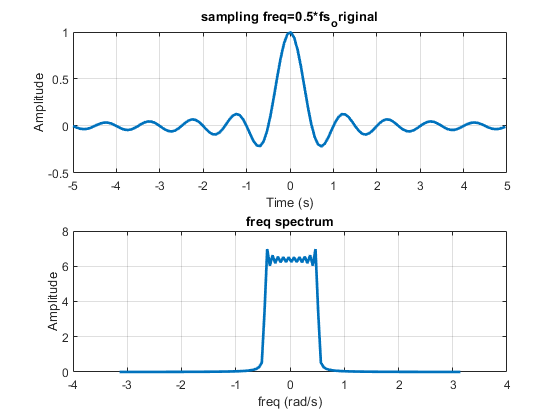


figure('Name', 'sampling freq=0.5*fs_original');
subplot(211)
plot(t1, x1, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('sampling freq=0.5*fs_original');
grid on;
subplot(212)
plot(f_axis1*2*pi/fs1, abs(fftshift(fft(x1))), 'LineWidth', 2);
xlabel('freq (rad/s)');
ylabel('Amplitude');
title('freq spectrum');
grid on;

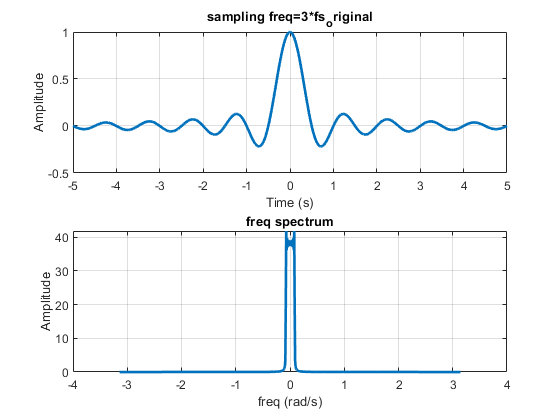


figure('Name', 'sampling freq=3*fs_original');
subplot(211)
plot(t2, x2, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('sampling freq=3*fs_original');
grid on;
subplot(212)
plot(f_axis2*2*pi/fs2, abs(fftshift(fft(x2))), 'LineWidth', 2);
xlabel('freq (rad/s)');
ylabel('Amplitude');
title('freq spectrum');
grid on;

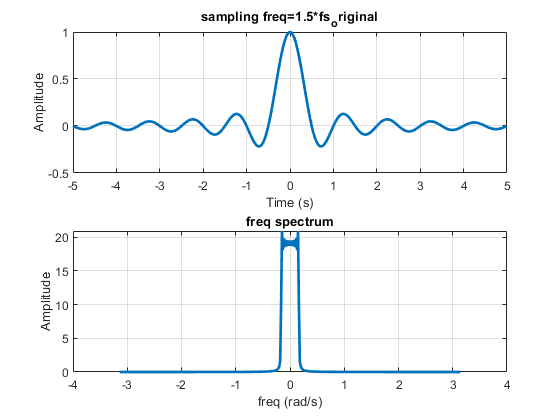



figure('Name', 'sampling freq=1.5*fs_original');
subplot(211)
plot(t3, x3, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('sampling freq=1.5*fs_original');
grid on;
subplot(212)
plot(f_axis3*2*pi/fs3, abs(fftshift(fft(x3))), 'LineWidth', 2);
xlabel('freq (rad/s)');
ylabel('Amplitude');
title('freq spectrum');
grid on;

As the sampling frequnecy increases, the spectrum of the signal gets tightened. that is because of the property of sampling.for more samples of a signal, the bandwidth is less expanded.